% Jeremiah Sullivan
% EC508, Wireless Communicaton
% Mini Project 3, April 2019
clc; close all; clear all;
%% Slow Fading Channels
% Consider a SIMO channel with L receive antennas,
%       y[m] = h x[m]+w[m]
%           where w[m] is i.i.d. CN (0, N_{0}I),
%           x[m] satisfies power constraint P,
%           h ~ CN (0, I) and is known only to the receiver.



## Part A

% To get started, write code to compute the closed-form outage capacity
% that we derived in class for the L = 1 case.
% Additionally, write code to find the outage capacity empirically.
%   For SNR = 0dB to 20dB (with 1dB spacing)
%   plot the capacity curves from these two methods for pout = 0.01, 0.05, 0.1.
%   (If you?ve done everything right, they should coincide.)
pOut    = [0.01, 0.05, 0.1];  SNRdb = 0:20;
SNR     = 10.^(SNRdb/10);
L       =     1;    % Diversity
M       = 1E5; % 1E6 == detailed, 1E5 == fast
h       = 1/sqrt(2) * randn(L,M) + 1j/sqrt(2) * randn(L,M);
hd      = sort(abs(h).^2); 
fprintf('The channel gains have a mean of %01.4f and a standard deviation of %1.4f', abs(mean(h)), std(h))

The channel gains have a mean of 0.0015 and a standard deviation of 0.9996

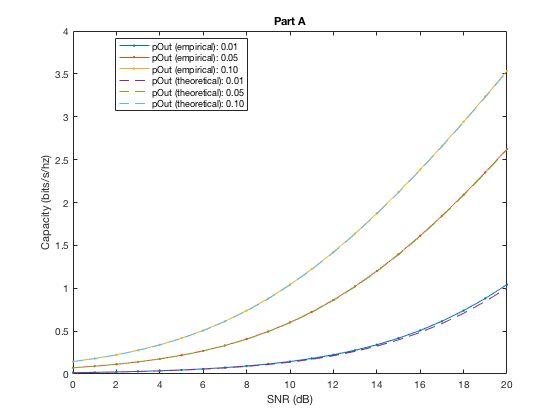


C = zeros(length(pOut), length(SNRdb));
for i = 1:length(pOut)
    E           = log2(1 + hd' .*SNR);
    C(i,:)      = E(M*pOut(i),:);    % take the value of the sorted trial in position pout×M.
end
figure;
plot(SNRdb, (C), '.-'); xlabel('SNR (dB)'); ylabel('Capacity (bits/s/hz)');
exactC = log2(1 + log( 1 ./ (1 - pOut')).*SNR);
hold on; plot(SNRdb, exactC, '--'); title('Part A');
legend([sprintfc('pOut (empirical): %01.2f', pOut'); (sprintfc('pOut (theoretical): %01.2f', pOut'))], 'location', 'best')

## Part B

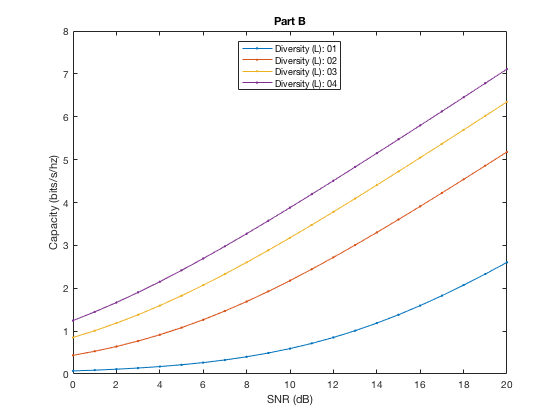

%  Generalize to any L
pOut = 0.05;
figure; clear C E Es;
L = 1:4;
for j = 1:length(L)
    h        = 1/sqrt(2) * randn(L(j),M) + 1j/sqrt(2) * randn(L(j),M); % Should be LxN
    hD       = sort(sum(abs(h).^2,1));
    for i = 1:length(pOut)
        E          = log2(1 + hD' .*SNR);  % Each SNR should form a column (ie, MxSNR);
        C(j,:)     = E(M*pOut(i),:);                                 % take the value of the sorted trial in position pout×M.
    end
end
plot(SNRdb, (C), '.-'); hold on;
xlabel('SNR (dB)'); ylabel('Capacity (bits/s/hz)'); title('Part B');
legend(sprintfc('Diversity (L): %02.0f', L), 'location', 'best');

## Part C:

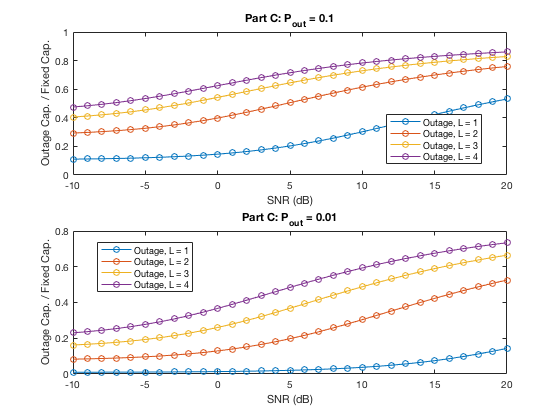


% Outage Capacity vs. Fixed Capacity
% Confused by ||h||^2 = L
M = 1E4; 
SNRdb = -10:20; SNR = 10.^(SNRdb./10);
pOut    = [0.1, 0.01];
for i = 1:length(pOut)
    for j = 1:length(L)
        h        = 1/sqrt(2) * randn(L(j),M) + 1j/sqrt(2) * randn(L(j),M); % Should be LxN
        hD       = sort(sum(abs(h).^2,1));
        E        = log2(1 + hD' .*SNR);  % Each SNR should form a column (ie, MxSNR);
        Co(j,:)  = E(M*pOut(i),:);                                 % take the value of the sorted trial in position pout×M.
        Cf(j,:)  = log2(1 + SNR*L(j));
    end
    subplot(2,1,i);h1 =  plot(SNRdb, (Co)./(Cf), 'o-'); 
    xlabel('SNR (dB)'); ylabel('Outage Cap. / Fixed Cap.');
    title(['Part C: P_{out} = ', num2str(pOut(i))]);
    legend(sprintfc('Outage, L = %01.0f',  L), 'location', 'best');
end

The diversity appears most beneficial withat medium-high SNR regions. Particularly when the probability of outage is lower. 

## Fix target rate

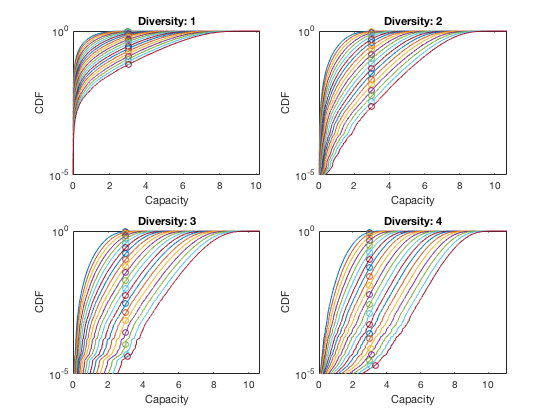

figure; clc;
SNRdb = 0:20; SNR = 10.^(SNRdb./10); L = 1:4;
R = 3; pOut = zeros(length(L), length(SNR));
M = 1E5; % Up the number of trials for this section only
parfor j = 1:length(L) % This may
    h        = 1/sqrt(2) * randn(L(j),M) + 1j/sqrt(2) * randn(L(j),M); % Should be LxN
    hD     = sort(sum(abs(h).^2,1));
    E        = log2(1 + hD' .*SNR);  % Each SNR should form a column (ie, MxSNR);
    if ~all((R > min(E)) & R< max(E)); warning([ 'Requested value not in range. L = ' num2str(L(j))]); end
    [~, I]  = min(abs(E - R));   % Find the closest value
    pOut(j, :) = I/M;                       % Transform that value into a probability
    if 1 % DEBUG
        subplot(2,2,j);
        plot(E, (1:length(h))./length(h)); hold on;
        ylabel('CDF');  xlabel('Capacity');
        for i = 1:length(SNR)
            plot(E(I(i), i), I(i)./length(h), 'o');
        end
        title(['Diversity: ', num2str(L(j))]);
        set(gca, 'YScale', 'log')
    end
end

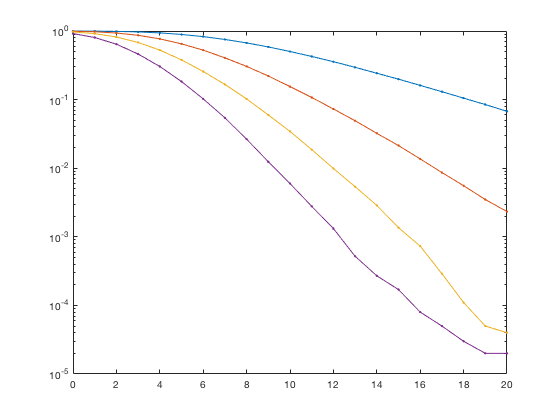

figure; semilogy(SNRdb, pOut, '.-'); %legend(sprintfc('Diversity (L): %02.0f ', L)); 

%xlabel('SNR (dB)'); ylabel('Probability of Outage'); title(sprintf('Probability of Outage for Fixed Capacity (R = %02.1f)', R)); 
% TEXT START
% This look like the curves for Probability of Error when sending a BPSK
% from mini-project 2. Essentially there appears to be diminishing returns
% when using higher and higher diversity levels. 
% TEXT END

# PROBLEM 2

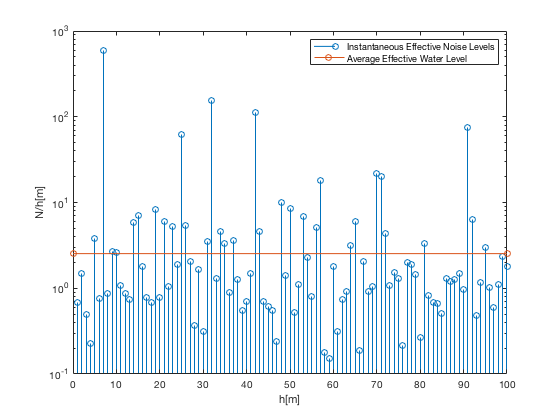

close all; clear all
SNRdb = 0; SNR = 10^(SNRdb/10); 
N = 1; P = SNR*N;  
% Let's generate 100 channel realizations, 100 times
% Given h is iid gaus(0,1)
M = 1E5; L = 1; 
h       = 1/sqrt(2) * randn(L,M) + 1j/sqrt(2) * randn(L,M);
[ht, I] = sort(abs(h).^2, 2); 
hd      = mean(ht,1); 
effNL      = sort(N./hd);
stem(effNL(1:00)); xlabel('h[m]'); ylabel('N/h[m]'); set(gca, 'YScale', 'log')
effPower = 0; i = 1; 
while effPower < P*M && i < length(effNL)
    effPower = effPower + (effNL(i+1) - effNL(i))*i; % This is some janky *ss code. 
    wl = effNL(i+1);                              % This is not exact, but who cares? 
    i = i+1; 
end
if i == length(h) % Did not fill all the buckets
   warning('Yo this aint tested')
   wl = wl + (P-effPower)./length(h);
else 
    lastLevel = i-1;
    wl = effNL(lastLevel); % Take a step back so you are below the power constraint
                  % This could be made exact, but... this is hard
                  % Let's try for lolz... 
    effPowerOld  = effPower -  (effNL(i) - effNL(i-1)).*(i-1); 
    partialLevel = (P*M - effPowerOld)./(i-1);
    wl           = effNL(i-1) + partialLevel; 
    err = sum(wl - effNL(1:i-1)) -  P*M;
    if 1E-8 < err
        warning(['Power level is off by ', num2str(err)])
    end
end
wfUnsort = 1./abs(h(1,:)).^2; % Take one random slice
stem(wfUnsort(1:100)); xlabel('h[m]'); ylabel('N/h[m]'); set(gca, 'YScale', 'log'); 
hold on; plot([0, 100], [wl, wl], 'o-'); hold off; 
legend('Instantaneous Effective Noise Levels', 'Average Effective Water Level');

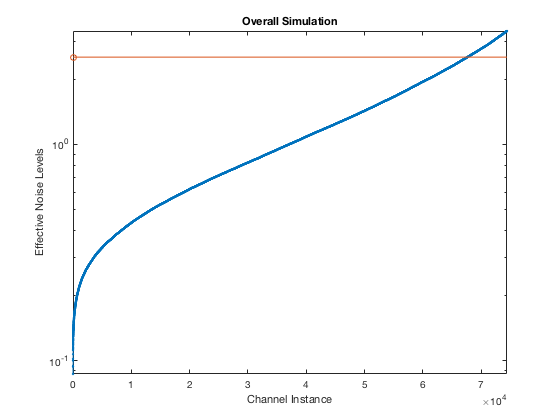

figure; plot(effNL, '.-'); hold on; plot([0, i], [wl, wl], 'o-'); set(gca, 'YScale', 'log')
xlabel('Channel Instance'); ylabel('Effective Noise Levels'); title('Overall Simulation'); 
xlim([0, i+i*0.1]); 

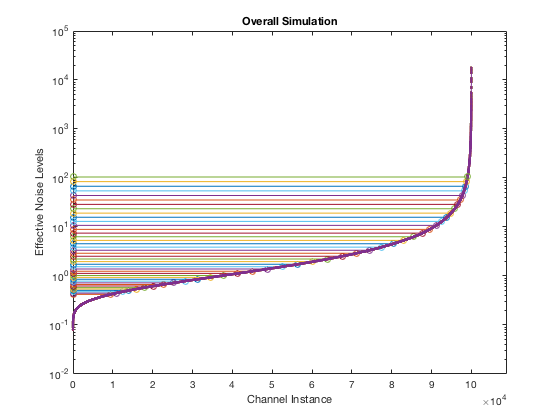

%% Part B
SNRdb = -20:20; SNR = 10.^(SNRdb/10); figure; 
N = 1;  % Noise power
M = 1E5; L = 1; 
h       = 1/sqrt(2) * randn(L,M) + 1j/sqrt(2) * randn(L,M);
[ht, I] = sort(abs(h).^2, 2); 
hd      = mean(ht,1); 
effNL      = sort(N./hd);

for ii = 1:length(SNR)
 P = SNR(ii)*N; 
effPower = 0; i = 1; 
while effPower < P*M && i < length(effNL)
    effPower = effPower + (effNL(i+1) - effNL(i))*i; % This is some janky *ss code. 
    wl = effNL(i+1);                              % This is not exact, but who cares? 
    i = i+1; 
end
if i == length(h) % Did not fill all the buckets
   warning('Yo this aint tested')
   wl = wl + (P-effPower)./length(h);
else 
        lastLevel = i-1;
        wl = effNL(lastLevel); % Take a step back so you are below the power constraint
                  % This could be made exact, but... this is hard
                  % Let's try for lolz... 
        effPowerOld  = effPower -  (effNL(i) - effNL(i-1)).*(i-1); 
        partialLevel = (P*M - effPowerOld)./(i-1);
        wl           = effNL(i-1) + partialLevel; 
        err = sum(wl - effNL(1:i-1)) -  P*M;
        if 1E-5 < err
            warning(['Power level is off by ', num2str(err)])
        end
end
Pm = (wl-effNL(1:(i-1))); 
h = sort(h); 
C1(ii) = sum(log2(1 + Pm.*abs(h((end-length(Pm)+1):end)).^2./N))./M;  % Can't use mean cuz average over M...
C2(ii) = mean(log2(1+(abs(h)).^2.*SNR(ii)));

plot(effNL, '.-'); hold on; plot([0, i], [wl, wl], 'o-'); set(gca, 'YScale', 'log')
xlabel('Channel Instance'); ylabel('Effective Noise Levels'); title('Overall Simulation'); hold on; 
xlim([0, i+i*0.1]); 
end

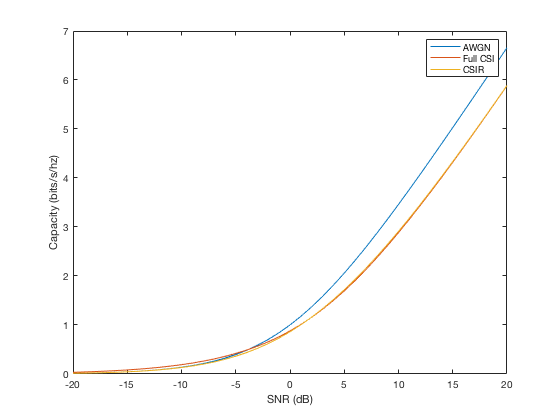

awgn = log2(1 + std(h) .* SNR./N); 
% hold on; plot([0, 100], [wl, wl], 'o-'); hold off;
% legend('Average Effective Noise Levels','Average Effective Water Level')

figure; 
plot(SNRdb, awgn); hold on; 
plot(SNRdb, C1)
plot(SNRdb, C2) 
xlabel('SNR (dB)'); ylabel('Capacity (bits/s/hz)'); 
legend('AWGN', 'Full CSI', 'CSIR')

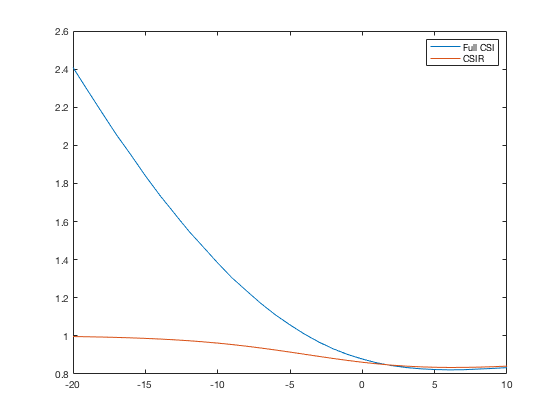

%% Part C
figure; xlabel('SNR (dB)');  ylabel('C/C_{awgn}') 
plot(SNRdb, C1./awgn); hold on; 
plot(SNRdb, C2./awgn); 
xlim([-20, 10]); legend('Full CSI', 'CSIR'); 